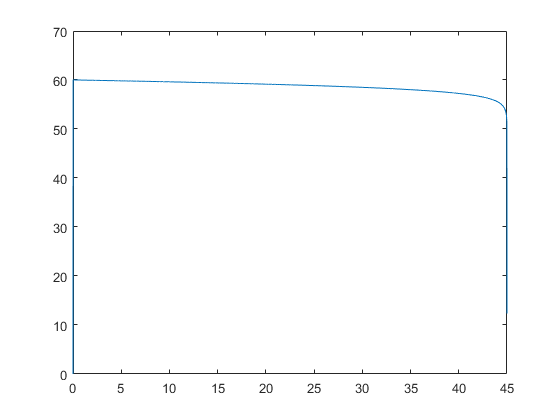

dT = 1e-2;
R = 8.3145;
Pstd = 101325;
nF = 2*96485;
C_act = 2;
A = 19.6*4.0;
T = 303.15;
Nfc = 50;
lambda = 14;
l = 21e-4 * 10^-2;
Rohm = 0;
Ifc = 0;
E_act = 0;
E_act_d = 0;
Ifc_ = [0];
E_act_ = [0];
E_Ner_ = [0];
E_con_ = [0];
E_ohm_ = [0];
T = 313;
Temp = 0;

while Ifc <= 45
    Ifc = Ifc + dT;
    
    %     https://link.springer.com/article/10.1007/s40565-016-0196-5
    %     Modeling and Simulation of a Proton Exchange Membrane Fuel Cell Alongside a Waste Heat Recovery System Based on the Organic Rankine Cycle in MATLAB/SIMULINK Environment
    %     MATHEMATICAL MODELLING FOR PROTON EXCHANGE MEMBRANE FUEL CELL (PEMFC)
    %     https://www.scirp.org/pdf/epe_2020112310053180.pdf#page=17&zoom=100,72,604
    %     H-Series Fuel Cell Stacks
    
    %% constants:
    J = Ifc/A;
    JM = 45/A;
    Pa = 1.45;
    Pc = 1;
    Tc = T-273.15;
    coeff = 1;
    
    PH2Osat = 10^(-2.18+2.95e-2*Tc-9.18e-5*Tc^2+1.44e-7*Tc^3);
    
    P_H2 = 0.5*PH2Osat*(exp(-(1.635*J/T^1.334))*(Pa/PH2Osat)-1);
    P_O2 = PH2Osat*(exp(-(4.192*J/T^1.334))*(Pc/PH2Osat)-1);
    
    
    %% Saturation at start
    if -1.87e-4*log(Ifc) > 0
        k = 0;
    else
        if -1.87e-4*log(Ifc) < -1.2
            k = -1.2;
        else
            k = -1.87e-4*log(Ifc);
        end
    end
    %% Nernst Voltage
    E_Ner = 1.229 + (T-298.15) * (-0.85e-3) + T*R/nF * log(P_H2*P_O2^0.5);
    
    %% Activation loss
    % Pressure not in Pa ?
    CO2 = (P_O2/(5.08e6))*exp(498/T);
    CH2 = (P_H2/(1.09e6))*exp(-77/T);
    E_act_steady=-0.9514 + T * (2.86e-3+2e-4*log(200)+4.3e-5*log(CH2)+7.4e-5*log(CO2)+k);
    %     E_act_steady = -0.9514 + 3.12e-3*T + 7.4e-5*T*log(CO2) -1.87e-4*T*log(Ifc);
    
    %% Ohmic loss
    E_ohm = - Ifc*(l/((lambda*5.139e-3-3.26e-3)*exp(1268*(1/303-1/T))));
    R_ohm = (l/((lambda*5.139e-3-3.26e-3)*exp(1268*(1/303-1/T))));
    
    %% Concentration loss
    %     if T>= 312.15
    %         E_con = (1.1e-4-1.2e-6*(T-273.15))*exp(8*Ifc/40);
    %     else
    %         E_con = (3.3e-3-8.2e-5*(T-273.15))*exp(8*Ifc/40);
    %     end
    
    %     E_con = 3*R*T/(2*nF)*log(1-J/JM)-1.5607*R*T/(2*nF);
    if J/JM < 1
        E_con = 3*R*T/(2*nF)*log(1-J/JM)-1.5607*R*T/(2*nF);
    else
        %         E_con = -abs(3*R*T/(2*nF)*log(complex(1-J/(JM-0.001)))-1.5607*R*T/(2*nF));
        E_con = 3*R*T/(2*nF)*log(J/JM)-1.5607*R*T/(2*nF);
    end
    
    %% with coefficient
    E_con = coeff * E_con;
    E_act_steady = coeff * E_act_steady;
    E_ohm = coeff * E_ohm;
    E_Ner = coeff * E_Ner;
    
    
    
    %% activation dynamic loss:
    below = -E_act_steady-E_con;
    E_act_d = (Ifc/C_act)*(1-E_act/below);
    
    E_act = trapz([E_act_(end) E_act_d]);
    
    %     E_act_d = 0;
    
    %% Fuel utilization
    U_H2 = 60000*Ifc*R*T*Nfc/(nF*1.16*1*0.9995*Pstd);
    
    %% Air utilization
    U_O2 = 60000*Ifc*R*T*Nfc/(2*nF*0.0181*1*0.21*Pstd);
    
    
    limit = 1;
    if J/JM >= 1
        E_con = 0;
        E_act_steady = 0;
        E_ohm = 0;
        E_act_d = 0;
        E_Ner = -35*Ifc;
        if E_Ner <= 0
            E_Ner = 0;
        end
        limit = 0;
    end
    
    E_act_ = [E_act_ E_act];
    E_con_ = [E_con_ E_con];
    E_Ner_ = [E_Ner_ E_Ner];
    E_ohm_ = [E_ohm_ E_ohm];
    Ifc_ = [Ifc_ Ifc];
    
    
end
Efc_ = Nfc.*(E_Ner_ + E_ohm_ + E_con_);
plot(Ifc_,Efc_)
xlim([0 45])

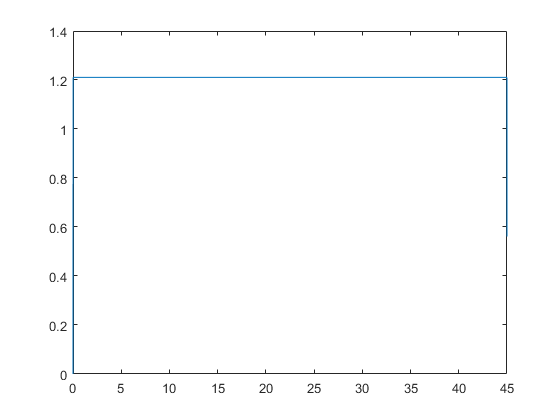

plot(Ifc_,E_Ner_)
xlim([0 45])

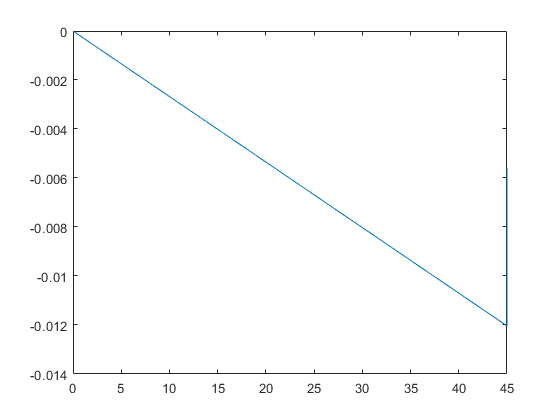

plot(Ifc_,E_ohm_)
xlim([0 45])

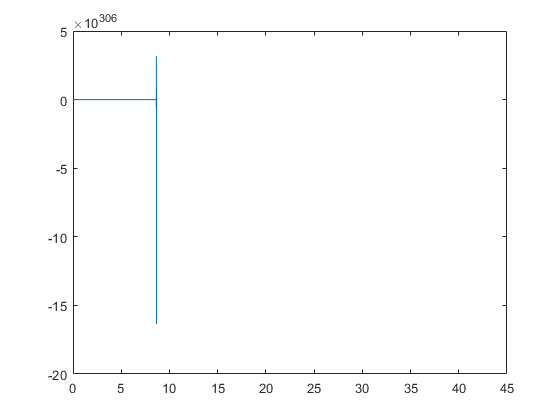

plot(Ifc_,E_act_)
xlim([0 45])

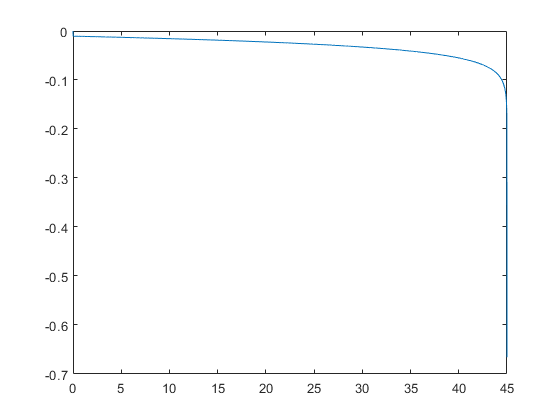

plot(Ifc_,E_con_)
% ylim([-2 2])
xlim([0 45])